## **Taller 1**

Mariana Sánchez Enciso, Santiago Romero Lozano

#### Punto 1

a) $e^x -4+x=0$

% Definir la función
f = @(x) exp(x) - 4 + x;
% Definir el intervalo inicial [a, b]
a = 1;
b = 2;
% Definir la tolerancia
tol = 1e-4;

%Para punto fijo
    % Definir la función g
    g = @(x) log(4-x);
    % Definir el valor inicial x0
    x0_pf = 1;
% Para Newton-Raphson
    df = @(x) exp(x) + 1; % Necesitamos la derivada de f
    x0_nr = 1 ;

[c_b,iter_b] = biseccion(f,a,b,tol);
[c_f,iter_f] = falsa_posicion(f,a,b,tol);
[x0_pf,iter_pf] = punto_fijo(g,x0_pf,tol);
[x0_nr,iter_nr] = newton_raphson(f,df,x0_nr,tol);
[x0_s,iter_s] = secante(f,a,b,tol);

Observamos la aproximación de cada uno de los métodos 

fprintf('La raíz aproximada con el método de bisección es %.6f\n', c_b);

La raíz aproximada con el método de bisección es 1.073730


fprintf('La raíz aproximada con el método de falsa posición es %.6f\n', c_f);

La raíz aproximada con el método de falsa posición es 1.073720


fprintf('La raíz aproximada con el método de punto fijo es %.6f\n', x0_pf);

La raíz aproximada con el método de punto fijo es 1.073715


fprintf('La raíz aproximada con el método de Newton-Raphson es %.6f\n', x0_nr);

La raíz aproximada con el método de Newton-Raphson es 1.073729


fprintf('La raíz aproximada con el método de Secante es %.6f\n', x0_s);

La raíz aproximada con el método de Secante es 1.073729


Ahora, miramos la cantidad de iteraciones de cada método

fprintf('Se realizaron %d iteraciones con el método de bisección\n', iter_b);

Se realizaron 11 iteraciones con el método de bisección


fprintf('Se realizaron %d iteraciones con el método de falsa posición\n', iter_f);

Se realizaron 8 iteraciones con el método de falsa posición


fprintf('Se realizaron %d iteraciones con el método de punto fijo\n', iter_pf);

Se realizaron 8 iteraciones con el método de punto fijo


fprintf('Se realizaron %d iteraciones con el método de Newton-Raphson\n', iter_nr);

Se realizaron 3 iteraciones con el método de Newton-Raphson


fprintf('Se realizaron %d iteraciones con el método de secante\n', iter_s);

Se realizaron 5 iteraciones con el método de secante


Con cada uno de los métodos se llega a la misma raíz, sin embargo el método de Newton-Raphson fue el más rápido, con únicamente 3 iteraciones. El promedio de iteraciones fue de 8. El más demorado fue el método de bisección.

b) $x-0\ldotp 2\sin \left(x\right)-0\ldotp 5=0$

% Definir la función
f = @(x) x - 0.2*sin(x) - 0.5;
% Definir el intervalo inicial [a, b]
a = 0;
b = 1;
% Definir la tolerancia
tol = 1e-4;

%Para punto fijo
    % Definir la función g
    g = @(x) 0.2*sin(x)+0.5;
    % Definir el valor inicial x0
    x0_pf = 0.5;
% Para Newton-Raphson
    df = @(x) 1-0.2*cos(x); % Necesitamos la derivada de f
    x0_nr = 0.5 ;

[c_b,iter_b] = biseccion(f,a,b,tol);
[c_f,iter_f] = falsa_posicion(f,a,b,tol);
[x0_pf,iter_pf] = punto_fijo(g,x0_pf,tol);
[x0_nr,iter_nr] = newton_raphson(f,df,x0_nr,tol);
[x0_s,iter_s] = secante(f,a,b,tol);

Observamos la aproximación de cada uno de los métodos 

fprintf('La raíz aproximada con el método de bisección es %.6f\n', c_b);

La raíz aproximada con el método de bisección es 0.615479


fprintf('La raíz aproximada con el método de falsa posición es %.6f\n', c_f);

La raíz aproximada con el método de falsa posición es 0.615455


fprintf('La raíz aproximada con el método de punto fijo es %.6f\n', x0_pf);

La raíz aproximada con el método de punto fijo es 0.615454


fprintf('La raíz aproximada con el método de Newton-Raphson es %.6f\n', x0_nr);

La raíz aproximada con el método de Newton-Raphson es 0.615468


fprintf('La raíz aproximada con el método de Secante es %.6f\n', x0_s);

La raíz aproximada con el método de Secante es 0.615468


Ahora, miramos la cantidad de iteraciones de cada método

fprintf('Se realizaron %d iteraciones con el método de bisección\n', iter_b);

Se realizaron 12 iteraciones con el método de bisección


fprintf('Se realizaron %d iteraciones con el método de falsa posición\n', iter_f);

Se realizaron 3 iteraciones con el método de falsa posición


fprintf('Se realizaron %d iteraciones con el método de punto fijo\n', iter_pf);

Se realizaron 5 iteraciones con el método de punto fijo


fprintf('Se realizaron %d iteraciones con el método de Newton-Raphson\n', iter_nr);

Se realizaron 3 iteraciones con el método de Newton-Raphson


fprintf('Se realizaron %d iteraciones con el método de secante\n', iter_s);

Se realizaron 5 iteraciones con el método de secante


Con cada uno de los métodos se llega a la misma raíz, sin embargo el método de Newton-Raphson y el método de falsa posición fueron los más rápidos, con únicamente 3 iteraciones. El promedio de iteraciones fue de 5. El más demorado fue el método de bisección.

c) $e^{\frac{x}{2}} -x^2 -3x=0$

% Definir la función
f = @(x) exp(x/2)-x.^2 - 3*x;
% Definir el intervalo inicial [a, b]
a = 0;
b = 1;
% Definir la tolerancia
tol = 1e-4;

%Para punto fijo
    % Definir la función g
    g = @(x) (exp(x/2)-x.^2)/3;
    % Definir el valor inicial x0
    x0_pf = 0.25;
% Para Newton-Raphson
    df = @(x) (1/2)*exp(x/2) -2*x - 3 ; % Necesitamos la derivada de f
    x0_nr = 0.25;

[c_b,iter_b] = biseccion(f,a,b,tol);
[c_f,iter_f] = falsa_posicion(f,a,b,tol);
[x0_pf,iter_pf] = punto_fijo(g,x0_pf,tol);
[x0_nr,iter_nr] = newton_raphson(f,df,x0_nr,tol);
[x0_s,iter_s] = secante(f,a,b,tol);

Observamos la aproximación de cada uno de los métodos 

fprintf('La raíz aproximada con el método de bisección es %.6f\n', c_b);

La raíz aproximada con el método de bisección es 0.356018


fprintf('La raíz aproximada con el método de falsa posición es %.6f\n', c_f);

La raíz aproximada con el método de falsa posición es 0.356001


fprintf('La raíz aproximada con el método de punto fijo es %.6f\n', x0_pf);

La raíz aproximada con el método de punto fijo es 0.356030


fprintf('La raíz aproximada con el método de Newton-Raphson es %.6f\n', x0_nr);

La raíz aproximada con el método de Newton-Raphson es 0.356029


fprintf('La raíz aproximada con el método de Secante es %.6f\n', x0_s);

La raíz aproximada con el método de Secante es 0.356029


Ahora, miramos la cantidad de iteraciones de cada método

fprintf('Se realizaron %d iteraciones con el método de bisección\n', iter_b);

Se realizaron 14 iteraciones con el método de bisección


fprintf('Se realizaron %d iteraciones con el método de falsa posición\n', iter_f);

Se realizaron 5 iteraciones con el método de falsa posición


fprintf('Se realizaron %d iteraciones con el método de punto fijo\n', iter_pf);

Se realizaron 3 iteraciones con el método de punto fijo


fprintf('Se realizaron %d iteraciones con el método de Newton-Raphson\n', iter_nr);

Se realizaron 3 iteraciones con el método de Newton-Raphson


fprintf('Se realizaron %d iteraciones con el método de secante\n', iter_s);

Se realizaron 6 iteraciones con el método de secante


Con cada uno de los métodos se llega a la misma raíz, sin embargo el método de Newton-Raphson y el método de punto fijo fueron los más rápidos, con únicamente 3 iteraciones. No se siguió un promedio en específico. El más demorado fue el método de bisección.

d) $e^x \cos \left(x\right)-x^2 +3x=0$

% Definir la función
f = @(x) exp(x)*cos(x) - x.^2 + 3*x;
% Definir el intervalo inicial [a, b]
a = 0;
b = 2;
% Definir la tolerancia
tol = 1e-4;

%Para punto fijo
    % Definir la función g
    %g = @(x) (x.^2 - exp(x)*cos/(x))/3;
    g = @(x) (-x.^2 + exp(x)*cos/(x) +3*x)/3;
    % Definir el valor inicial x0
    x0_pf = 1.5;

% Para Newton-Raphson
    df = @(x) (exp(x)*cos(x)) - (exp(x)*sin(x)) - 2*x + 3; % Necesitamos la derivada de f
    x0_nr = 1.5;

[c_b,iter_b] = biseccion(f,a,b,tol);
[c_f,iter_f] = falsa_posicion(f,a,b,tol);

[x0_nr,iter_nr] = newton_raphson(f,df,x0_nr,tol);
[x0_s,iter_s] = secante(f,a,b,tol);

Observamos la aproximación de cada uno de los métodos 

fprintf('La raíz aproximada con el método de bisección es %.6f\n', c_b);

La raíz aproximada con el método de bisección es 1.892258


fprintf('La raíz aproximada con el método de falsa posición es %.6f\n', c_f);

La raíz aproximada con el método de falsa posición es 1.892251


fprintf('La raíz aproximada con el método de punto fijo es %.6f\n', x0_pf);

La raíz aproximada con el método de punto fijo es 1.500000


fprintf('La raíz aproximada con el método de Newton-Raphson es %.6f\n', x0_nr);

La raíz aproximada con el método de Newton-Raphson es 1.892257


fprintf('La raíz aproximada con el método de Secante es %.6f\n', x0_s);

La raíz aproximada con el método de Secante es 1.892257


Ahora, miramos la cantidad de iteraciones de cada método

fprintf('Se realizaron %d iteraciones con el método de bisección\n', iter_b);

Se realizaron 17 iteraciones con el método de bisección


fprintf('Se realizaron %d iteraciones con el método de falsa posición\n', iter_f);

Se realizaron 6 iteraciones con el método de falsa posición


fprintf('Se realizaron %d iteraciones con el método de punto fijo\n', iter_pf);

Se realizaron 3 iteraciones con el método de punto fijo


fprintf('Se realizaron %d iteraciones con el método de Newton-Raphson\n', iter_nr);

Se realizaron 5 iteraciones con el método de Newton-Raphson


fprintf('Se realizaron %d iteraciones con el método de secante\n', iter_s);

Se realizaron 8 iteraciones con el método de secante


Para este punto no fue posible encontrar una función g que satisfaga las propiedades para realizar la aproximación por punto fijo con el error establecido. Además el método de Newton-Raphson fue el más rápido, con 5 iteraciones. No se siguió un promedio en específico. El más demorado fue el método de bisección.

e) $0\ldotp 5x^3 +x^2 -2x-5=0$

% Definir la función
f = @(x) 0.5 * x.^3 + x.^2 - 2*x -5;
% Definir el intervalo inicial [a, b]
a = 1;
b = 3;
% Definir la tolerancia
tol = 1e-4;

%Para punto fijo
    % Definir la función g
    g = @(x) sqrt(x.^2 -0.5*x.^3+5);
    % Definir el valor inicial x0
    x0_pf = 2;
% Para Newton-Raphson
    df = @(x) 1.5*x.^2 + 2*x - 2; % Necesitamos la derivada de f
    x0_nr = 2;

[c_b,iter_b] = biseccion(f,a,b,tol);
[c_f,iter_f] = falsa_posicion(f,a,b,tol);
[x0_pf,iter_pf] = punto_fijo(g,x0_pf,tol);
[x0_nr,iter_nr] = newton_raphson(f,df,x0_nr,tol);
[x0_s,iter_s] = secante(f,a,b,tol);

Observamos la aproximación de cada uno de los métodos 

fprintf('La raíz aproximada con el método de bisección es %.6f\n', c_b);

La raíz aproximada con el método de bisección es 2.117950


fprintf('La raíz aproximada con el método de falsa posición es %.6f\n', c_f);

La raíz aproximada con el método de falsa posición es 2.117937


fprintf('La raíz aproximada con el método de punto fijo es %.6f\n', x0_pf);

La raíz aproximada con el método de punto fijo es 2.154471


fprintf('La raíz aproximada con el método de Newton-Raphson es %.6f\n', x0_nr);

La raíz aproximada con el método de Newton-Raphson es 2.117942


fprintf('La raíz aproximada con el método de Secante es %.6f\n', x0_s);

La raíz aproximada con el método de Secante es 2.117942


Ahora, miramos la cantidad de iteraciones de cada método

fprintf('Se realizaron %d iteraciones con el método de bisección\n', iter_b);

Se realizaron 16 iteraciones con el método de bisección


fprintf('Se realizaron %d iteraciones con el método de falsa posición\n', iter_f);

Se realizaron 11 iteraciones con el método de falsa posición


fprintf('Se realizaron %d iteraciones con el método de punto fijo\n', iter_pf);

Se realizaron 17 iteraciones con el método de punto fijo


fprintf('Se realizaron %d iteraciones con el método de Newton-Raphson\n', iter_nr);

Se realizaron 3 iteraciones con el método de Newton-Raphson


fprintf('Se realizaron %d iteraciones con el método de secante\n', iter_s);

Se realizaron 7 iteraciones con el método de secante


Para este punto no fue posible encontrar una función g que satisfaga las propiedades para realizar la aproximación por punto fijo con el error establecido. Además el método de Newton-Raphson fue el más rápido, con 3 iteraciones. No se siguió un promedio en específico. El más demorado fue el método de punto fijo, que además no llega a la raíz.

f) $e^x -4x^2 -8x=0$

% Definir la función
f = @(x) exp(x) - 4*x.^2 - 8*x;
% Definir el intervalo inicial [a, b]
a = 0;
b = 1;
% Definir la tolerancia
tol = 1e-4;

%Para punto fijo
    % Definir la función g
    g = @(x) (exp(x) - 4*x.^2)/9;
    % Definir el valor inicial x0
    x0_pf = 0.1;
% Para Newton-Raphson
    df = @(x) exp(x) - 8*x - 8; % Necesitamos la derivada de f
    x0_nr = 0.1 ;

[c_b,iter_b] = biseccion(f,a,b,tol);
[c_f,iter_f] = falsa_posicion(f,a,b,tol);
[x0_pf,iter_pf] = punto_fijo(g,x0_pf,tol);
[x0_nr,iter_nr] = newton_raphson(f,df,x0_nr,tol);
[x0_s,iter_s] = secante(f,a,b,tol);

Observamos la aproximación de cada uno de los métodos 

fprintf('La raíz aproximada con el método de bisección es %.6f\n', c_b);

La raíz aproximada con el método de bisección es 0.133942


fprintf('La raíz aproximada con el método de falsa posición es %.6f\n', c_f);

La raíz aproximada con el método de falsa posición es 0.133934


fprintf('La raíz aproximada con el método de punto fijo es %.6f\n', x0_pf);

La raíz aproximada con el método de punto fijo es 0.118855


fprintf('La raíz aproximada con el método de Newton-Raphson es %.6f\n', x0_nr);

La raíz aproximada con el método de Newton-Raphson es 0.133946


fprintf('La raíz aproximada con el método de Secante es %.6f\n', x0_s);

La raíz aproximada con el método de Secante es 0.133946


Ahora, miramos la cantidad de iteraciones de cada método

fprintf('Se realizaron %d iteraciones con el método de bisección\n', iter_b);

Se realizaron 15 iteraciones con el método de bisección


fprintf('Se realizaron %d iteraciones con el método de falsa posición\n', iter_f);

Se realizaron 7 iteraciones con el método de falsa posición


fprintf('Se realizaron %d iteraciones con el método de punto fijo\n', iter_pf);

Se realizaron 3 iteraciones con el método de punto fijo


fprintf('Se realizaron %d iteraciones con el método de Newton-Raphson\n', iter_nr);

Se realizaron 3 iteraciones con el método de Newton-Raphson


fprintf('Se realizaron %d iteraciones con el método de secante\n', iter_s);

Se realizaron 6 iteraciones con el método de secante


Para este punto no fue posible encontrar una función g que satisfaga las propiedades para realizar la aproximación por punto fijo con el error establecido. Además el método de Newton-Raphson fue el más rápido, con 3 iteraciones. No se siguió un promedio en específico. El más demorado fue el método debisección.

#### Punto 2

 a) v = 36m/s, c = 15kg/s en t=10s

v = 36;
g = 9.81;
c = 15;
t = 10;

f = @(m) v-((g*m)/c)*(1-exp(-((c/m)*t)));
tol = 0.0002;

%Bisección
[c,iter] = biseccion(f,1,100,tol);
fprintf('La raíz aproximada es %.6f\n', c);

La raíz aproximada es 59.959503


fprintf('Se realizaron %d iteraciones\n', iter);

Se realizaron 15 iteraciones


%Falsa Posición
[c,iter] = falsa_posicion(f,1,100,tol);
fprintf('La raíz aproximada es %.6f\n', c);

La raíz aproximada es 59.959598


fprintf('Se realizaron %d iteraciones\n', iter);

Se realizaron 8 iteraciones


b)  m = 82kg, v=36m/s, después de t=4s

v = 36;
g = 9.81;
m = 82;
t = 4;

f = @(c) v-((g*m)/c)*(1-exp(-((c/m)*t)));
%Bisección
[c,iter] = biseccion(f,1,100,tol);
fprintf('La raíz aproximada es %.6f\n', c);

La raíz aproximada es 3.585426


fprintf('Se realizaron %d iteraciones\n', iter);

Se realizaron 17 iteraciones


%Falsa Posición
[c,iter] = falsa_posicion(f,1,100,tol);
fprintf('La raíz aproximada es %.6f\n', c);

La raíz aproximada es 3.585547


fprintf('Se realizaron %d iteraciones\n', iter);

Se realizaron 5 iteraciones


#### Punto 3

Como nos piden el máximo, lo evaluaremos con respecto a la derivada de f(x), el cuál es nuestra nueva f

f = @(x) -12*x^5-6*x^3+10; 
tol = 0.0005;

a) Punto Fijo

g = @(x) (-10/(-12*x^2-6))^(1/3);
x0 = 0.05;
[c,iter] = punto_fijo(g,x0,tol);
fprintf('La raíz aproximada es %.6f\n', c);

La raíz aproximada es 0.871333


fprintf('Se realizaron %d iteraciones\n', iter);

Se realizaron 10 iteraciones


b) Newton-Raphson

df = @(x) -60*x^4-18*x^2;
x0 = 1;

[x0,iter] = newton_raphson(f,df,x0,tol);

fprintf('La raíz aproximada es %.6f\n', x0);

La raíz aproximada es 0.871411


fprintf('Se realizaron %d iteraciones\n', iter);

Se realizaron 4 iteraciones


c) Secante

[x0,iter] = secante(f,0,1,tol);

fprintf('La raíz aproximada es %.6f\n', x0);

La raíz aproximada es 0.871411


fprintf('Se realizaron %d iteraciones\n', iter);

Se realizaron 8 iteraciones


d) Técnica más adecuada para el problema

 La más adecuada para este problema es Newton-Raphson puesto que es el método que llega al resultado con menos iteraciones

#### Punto 4

.

#### Punto 5

.

#### Punto 6

.

#### Punto 7

a) Gráfico de la función en [-1,1]

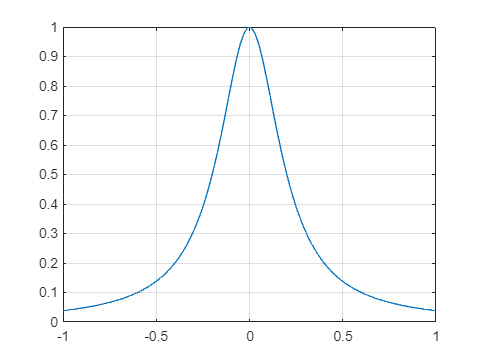

f =  @(x) 1./(1 + 25 *x.^2);
x = linspace(-1, 1, 100);
plot(x, f(x));
grid on;